## Lesson 6

### Data

The data that will be use for this lesson is coming directly from recordings in the prelimbic cortex while mice are performing a task.

**Task Description**

In this behavioral task, the animal makes a **choice between two sides** — **Left** or **Right** — on each trial.

- One side is designated as the **Gamble side**, and the other as the **Safe side**.

- The **Gamble side** offers a **reward with a variable probability**, which changes across different blocks of the session.

- The **Safe side** always provides a **reward with a fixed probability of 90%**.

The animal is **free to choose** which side to select on every trial.

Each trial follows a structured sequence:

- **Wheel Stop:**The animal begins the trial by stopping a wheel and waiting for **one second**.

- **Cue Presentation:**A cue appears, signaling that the animal can make a choice.

- **Choice Phase:**The animal selects either the **Gamble** or **Safe** side (Left or Right).

- **Outcome:**The chosen side determines whether a **reward** is delivered, based on the corresponding probability.

- **Inter-trial Interval:**After receiving (or not receiving) the reward, the animal waits **two seconds**.It then decides **when to initiate the next trial** by stopping the wheel again.

You have 2 different matrices.

STMtx -> where each column is a neuon and in the rows you have the spike times of that neuron (in seconds).

Trial_Sync -> A behavioural Matrix indicanting information. Rows are trials and columns are:

1   'Trial Start (seconds from behavioural start)'

2   'Trial End (seconds from behavioural start)'

3   'Trial duration (seconds) (from the synchronisation)'

4   'Block number'

5   'Gamble Arm (Right = 1, Left = 0)'

6   'Probability Big Reward'

7   'Probability Small Reward'

8   'Ammount Big Reward'

9   'Ammount Small Reward'

10  'Number of previous wheel not stopping'

11  'Not responding trial'

12  'Chosen side (Right = 1, Left = 0)'

13  'Chosen arm (Gamble = 1, Safe = 0)'

14  'Rewarded trial'

15  'Start of the trial (Sampling points)' - the sampling rate is 20000 hz (To convert to seconds, divide sampling points by sampling rate)

16  'Cue presentation (Sampling points)'

17  'Start of response window (Sampling points)'

18  'Reward Period (Sampling points)'

19  'End of the trial (Sampling points)'

We are going to explore this data set to understand better which analyses are possible.

## 1) Firing rate

We can calculate the firing rate of a neuron by counting the number of spikes during a given time.

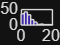

% Calculating the firing rate of the first neuron of the STMtx matrix
load STMtx

Spike_Times = STMtx(~isnan(STMtx(:,1)),1);

Number_Spikes = length(Spike_Times);
Time = Spike_Times(end) - Spike_Times(1);
Firing_Rate = Number_Spikes/Time;

% FOR YOU!!
% Please comment each line explaining what is happening
% Create a script that calculates for each neuron and stores it in a
% vector where each element is the Firing rate of one neuron

% The vector you create should be the same as the data given FR.mat

% We can do an histogram to check the distribution of Firing rates
hist(FR)


% FOR YOU!!
% use the documentation of hist to play with the number of bins. 
% What is your conclusion of the distribution of firing rates?


## 2) Some behavioural measurements

Because we have a behavioural matrix, we could inspect the data

% If we want to know how many times the animal was rewarded, we can check
% the column number 14 "Rewarded Trial". In this column, a 1 means rewarded
% and a 0 means not rewarded. If I sum the ones in that column, it will
% tell me the number of times the animal got rewarded

Times_Rewarded = sum(Trials_Sync(:,14));
Percentage_Rewarded = Times_Rewarded/size(Trials_Sync,1); 

% FOR YOU!!
% Explain what we did in the Percentage_Rewarded line
% We have a column "Chosen arm" whoch is 1 for gamble and 0 for safe.
% Calculate the percentage of times that the animal got rewarded in gamble,
% and the percentage of times that it got rewarded in safe.
% TIP: You first need to find the indexes for gamble and safe, and then
% extract the rewarded information of those indexes

% Then, do the same, but for each block. Explain what you see.


## 3) Firing rate comparisons

We can compare the firing rates of diferent neurons on each block

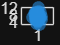

% Finding the indexes for Block 1
Block1_Index = Trials_Sync(:,4) == 1;
Block2_Index = Trials_Sync(:,4) == 2;
Block3_Index = Trials_Sync(:,4) == 3;

% Extracting the behavioural data per blocks
Block1_Trials_Sync = Trials_Sync(Block1_Index,:);
Block2_Trials_Sync = Trials_Sync(Block2_Index,:);
Block3_Trials_Sync = Trials_Sync(Block3_Index,:);

SR = 20000; % We will need the Sampling Rate (SR)

% For block 1, find the firing rates of each neuron for each trial
for i = 1:size(Block1_Trials_Sync,1) % A for loop that will go for each trial in block 1
    for ii = 1:size(STMtx,2) % a for loop that will go for each neuron
        Spike_Times = STMtx(:,ii);
        Spikes_per_trial = sum(Spike_Times>(Block1_Trials_Sync(i,15)./SR) & Spike_Times<(Block1_Trials_Sync(i,19)./SR));
        Firing_Rate_Block1(i,ii) = Spikes_per_trial/((Block1_Trials_Sync(i,19)-Block1_Trials_Sync(i,15))./SR);
    end
end

% FOR YOU!!
% Explain the code
% Create also the Firing rate matrices for the other blocks.

% You should end up with the same matrices that the ones in the
% Firing_Blocks.mat

% We can use boxplot to check how different neurons change their firing
% rate. Also, to plot each point
boxplot(Firing_Rate_Block1(:,1))
hold on
for i = 1:length(Firing_Rate_Block1(:,1))
    x = randn(length(Firing_Rate_Block1(:,1)),1)*0.05 + i; % jitter around box position
    y = Firing_Rate_Block1(:,1);
    scatter(x, y, 40, 'filled', 'MarkerFaceAlpha', 0.6)
end


% We can also observed for a neuron in different blocks

Neuron_ID = 1;
data = [Firing_Rate_Block1(:,Neuron_ID); Firing_Rate_Block2(:,Neuron_ID); Firing_Rate_Block3(:,Neuron_ID)];
group = [ones(length(Firing_Rate_Block1(:,Neuron_ID)),1); 2*ones(length(Firing_Rate_Block2(:,Neuron_ID)),1); 3*ones(length(Firing_Rate_Block3(:,Neuron_ID)),1)];

Error using ones
Size inputs must be scalar.


figure; 
boxplot(data, group); % no outlier symbols
hold on

% Overlay data points (with horizontal jitter)
g = unique(group);
for i = 1:length(g)
    x = randn(sum(group==g(i)),1)*0.05 + i; % jitter around box position
    y = data(group==g(i));
    scatter(x, y, 40, 'filled', 'MarkerFaceAlpha', 0.6)
end

% FOR YOU!!
% Find 3 neurons that increase their firing rate during the blocks and 3 neurons that
% decrease their firing rate during the blocks
% Then, plot one figure where in the top three sub figure you have the 3
% increasing and at the bottom the 3 decreasing. Label the plots with
% the neuron ID


## 4) Autocorrelograms